# DCモータ電流制御PI制御器設計（極配置法）

clear; close all; clc;

## パラメータの設定

load("estimate_parameters\parameters.mat");

%% 1. システムパラメータの定義
Kt = p_Kt;    % トルク定数 [Nm/A]
Ke = p_Ke;    % 逆起電力定数 [V*s/rad]
La = p_La;    % 電機子インダクタンス [H]
Ra = p_Ra;    % 電機子抵抗 [Ω]

% 時定数の計算
tau_a = La/Ra;  % 電機子回路時定数 [s]

fprintf('=== システムパラメータ ===\n');

=== システムパラメータ ===


fprintf('電機子抵抗 Ra = %.1f [Ω]\n', Ra);

電機子抵抗 Ra = 32.4 [Ω]


fprintf('電機子インダクタンス La = %.3f [H]\n', La);

電機子インダクタンス La = 0.003 [H]


fprintf('電機子回路時定数 τa = %.3e [s]\n', tau_a);

電機子回路時定数 τa = 9.120e-05 [s]


fprintf('制約条件: p1 + p2 > %.1f [rad/s]\n\n', 1/tau_a);

制約条件: p1 + p2 > 10964.5 [rad/s]



%% 2. プラントの伝達関数
% Gp(s) = 1/(La*s + Ra) = (1/Ra)/(tau_a*s + 1)
num_p = 1;
den_p = [La Ra];
Gp = tf(num_p, den_p);

fprintf('=== プラント伝達関数 ===\n');

=== プラント伝達関数 ===


fprintf('Gp(s) = 1/(%.3f*s + %.1f)\n\n', La, Ra);

Gp(s) = 1/(0.003*s + 32.4)



%% 3. 希望極の設定
% 重根配置の例
p1 = 6000;  % 第1極 [rad/s]
p2 = 6000;  % 第2極 [rad/s]

% 制約条件の確認
if (p1 + p2) <= 1/tau_a
    warning('極の和が制約条件を満たしていません！');
    fprintf('p1 + p2 = %.1f <= 1/τa = %.1f\n', p1+p2, 1/tau_a);
end

fprintf('=== 希望極配置 ===\n');

=== 希望極配置 ===


fprintf('p1 = %.0f [rad/s]\n', p1);

p1 = 6000 [rad/s]


fprintf('p2 = %.0f [rad/s]\n', p2);

p2 = 6000 [rad/s]


fprintf('時定数: 1/p1 = %.3f [ms]\n\n', 1000/p1);

時定数: 1/p1 = 0.167 [ms]



%% 4. PI制御器パラメータの計算
% 極配置法による設計
Kp = Ra * (tau_a*(p1 + p2) - 1);
Ti = (tau_a*(p1 + p2) - 1) / (tau_a*p1*p2);
Ki = Kp / Ti;

fprintf('=== PI制御器パラメータ ===\n');

=== PI制御器パラメータ ===


fprintf('比例ゲイン Kp = %.3f\n', Kp);

比例ゲイン Kp = 3.060


fprintf('積分ゲイン Ki = %.0f [1/s]\n', Ki);

積分ゲイン Ki = 106380 [1/s]


fprintf('積分時間 Ti = %.3e [s]\n\n', Ti);

積分時間 Ti = 2.876e-05 [s]



%% 5. PI制御器の伝達関数
% Gc(s) = Kp + Ki/s = Kp*(Ti*s + 1)/(Ti*s)
num_c = Kp*[Ti 1];
den_c = [Ti 0];
Gc = tf(num_c, den_c);

%% 6. 開ループ・閉ループ系の構築
% 開ループ伝達関数
Go = Gc * Gp;

% 閉ループ伝達関数
Gcl = feedback(Go, 1);

%% 7. 特性方程式の確認
[num_cl, den_cl] = tfdata(Gcl, 'v');
poles_cl = roots(den_cl);

fprintf('=== 閉ループ極の確認 ===\n');

=== 閉ループ極の確認 ===


fprintf('設計極: s = -%.0f, -%.0f\n', p1, p2);

設計極: s = -6000, -6000


fprintf('実際の極: s = %.1f, %.1f\n', real(poles_cl(1)), real(poles_cl(2)));

実際の極: s = -6000.0, -6000.0


fprintf('誤差: %.2e\n\n', norm([p1; p2] + poles_cl));

誤差: 1.22e-04



%% 8. 応答特性の計算
% 立ち上がり時間と整定時間の推定
tr_est = 2.2/p1;  % 立ち上がり時間の推定値 [s]
ts_est = 4/p1;    % 整定時間（2%）の推定値 [s]

fprintf('=== 応答特性（推定値） ===\n');

=== 応答特性（推定値） ===


fprintf('帯域幅: %.0f [rad/s] ≈ %.0f [Hz]\n', p1, p1/(2*pi));

帯域幅: 6000 [rad/s] ≈ 955 [Hz]


fprintf('立ち上がり時間: %.3f [ms]\n', tr_est*1000);

立ち上がり時間: 0.367 [ms]


fprintf('整定時間（2%%）: %.3f [ms]\n\n', ts_est*1000);

整定時間（2%）: 0.667 [ms]



%% 9. ステップ応答の描画
figure(1);
subplot(2,1,1);
step(Gcl, 0.005);  % 5msまで表示
grid on;
title('閉ループステップ応答（電流指令値に対する電流応答）');
xlabel('時間 [s]');
ylabel('電流 [A/A]');

% ステップ応答情報の取得
stepinfo_cl = stepinfo(Gcl);
fprintf('=== ステップ応答特性（実測値） ===\n');

=== ステップ応答特性（実測値） ===


fprintf('立ち上がり時間: %.3f [ms]\n', stepinfo_cl.RiseTime*1000);

立ち上がり時間: 0.555 [ms]


fprintf('整定時間（2%%）: %.3f [ms]\n', stepinfo_cl.SettlingTime*1000);

整定時間（2%）: 0.941 [ms]


fprintf('オーバーシュート: %.1f [%%]\n', stepinfo_cl.Overshoot);

オーバーシュート: 0.0 [%]


fprintf('ピーク時間: %.3f [ms]\n\n', stepinfo_cl.PeakTime*1000);

ピーク時間: 2.295 [ms]



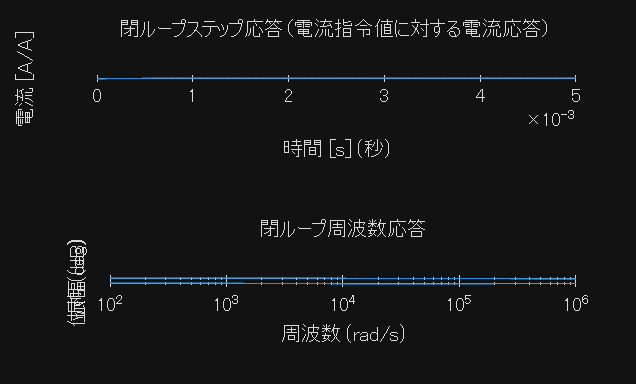

%% 10. 周波数応答の描画
subplot(2,1,2);
bode(Gcl);
grid on;
title('閉ループ周波数応答');

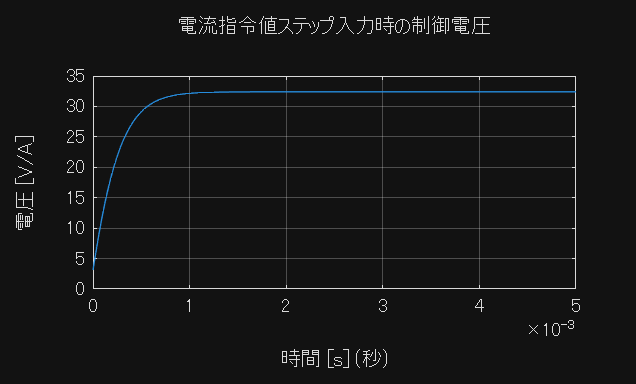

%% 11. 制御入力（電圧）の確認
figure(2);
% 電流指令値から電圧までの伝達関数
Gv = Gc / (1 + Go);
step(Gv, 0.005);
grid on;
title('電流指令値ステップ入力時の制御電圧');
xlabel('時間 [s]');
ylabel('電圧 [V/A]');

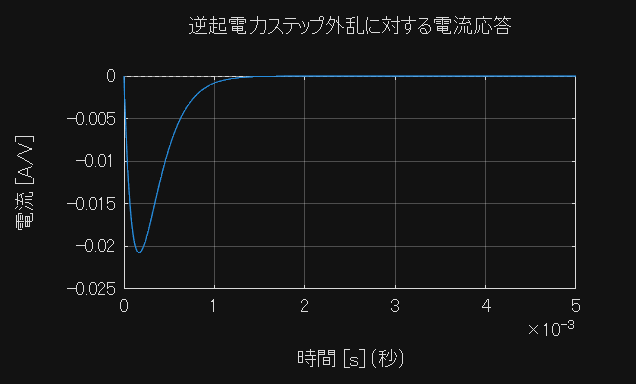

%% 12. 外乱（逆起電力）に対する応答
figure(3);
% 逆起電力から電流への伝達関数
Gd = -Gp / (1 + Go);
step(Gd, 0.005);
grid on;
title('逆起電力ステップ外乱に対する電流応答');
xlabel('時間 [s]');
ylabel('電流 [A/V]');

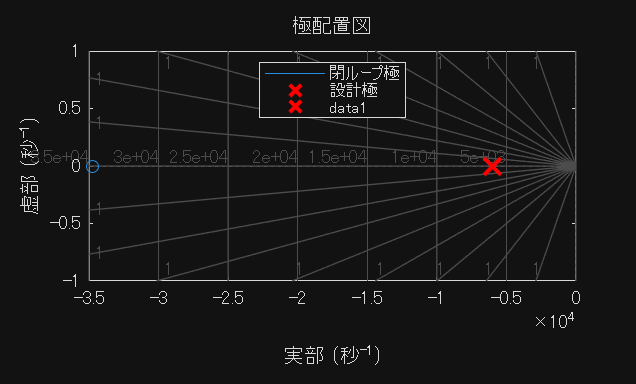

%% 13. 極配置の可視化
figure(4);
pzmap(Gcl);
hold on;
plot(-p1, 0, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
plot(-p2, 0, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
legend('閉ループ極', '設計極', 'Location', 'best');
grid on;
title('極配置図');
xlabel('実部');
ylabel('虚部');

%% 14. 設計結果のまとめ表示
fprintf('\n=== 設計結果サマリー ===\n');


=== 設計結果サマリー ===


fprintf('プラント時定数: τa = %.3e [s] (%.2f [ms])\n', tau_a, tau_a*1000);

プラント時定数: τa = 9.120e-05 [s] (0.09 [ms])


fprintf('PI制御器: Kp = %.3f, Ki = %.0f [1/s]\n', Kp, Ki);

PI制御器: Kp = 3.060, Ki = 106380 [1/s]


fprintf('閉ループ帯域: %.0f [Hz]\n', p1/(2*pi));

閉ループ帯域: 955 [Hz]


fprintf('応答速度: 立ち上がり %.3f [ms], 整定 %.3f [ms]\n', ...
    stepinfo_cl.RiseTime*1000, stepinfo_cl.SettlingTime*1000);

応答速度: 立ち上がり 0.555 [ms], 整定 0.941 [ms]
